# Code 6: Sensitivity analysis of Magnitude Uncertainty

by Nithin Sivadas Input Data Files

%Specify the folder where all the data is stored. See: https://nithinsivadas.github.io/polar-cap-saturation/
DataDir = 'Data/';

Including heteroskedastic uncertainty functions from calculated uncertainty using simultaneous magnetosheath measurements. This uncertainty was then fitted into a spline function.

load([DataDir,'uncertainty_functions.mat']);

Set this to 1, if you want to use previous run of random variables. Set this to 0, if you want to carry out a new run (which will take some more time, and make minor changes in the plots because of randomness and differences in sampling each time).

setLoadExistingData=1;
if setLoadExistingData==1
    %load([DataDir,'polar_cap_previous_run.mat']);
    load([DataDir,'polar_cap_essential_run.mat']);
end

Set this to 1 if you wish to save the images onto a folder, or 0 if you just would like to view it

setExportFig = 0;

% Output Folder

%Specify the output folder where you'd like to store the images
outputFolder = 'results/';

Using previously saved data

if ~setLoadExistingData
    [wind, pci, Fsml, Xm, XmTime, Fpcc, acf_fit_Xm, acf_fit_PCC, acf_fit_var]= initialize(superMagFile,windDataFolder,polarCapDataFolder);
end
% Requires
% Mapping Toolbox
% Image processing toolbox
PCC = Fpcc(datenum(XmTime));

dt = 1; % 1 min intervals
nSamplesM = 2^12; % Upto 80 hours
nEnsemblesM =16000;
lag = fftshift(-nSamplesM:1:nSamplesM-1)'.*dt;

% Generating auto-correlation matrices for the model
Rm = acf_fit_PCC(abs(lag));
RmErr = acf_fit_var(abs(lag));

% Input 2 : The autocorrelation matrix/function
RmMatrix = toeplitz(Rm(find(lag==0):find(lag==(nSamplesM-1)*dt)));
RmErrMatrix = toeplitz(RmErr(find(lag==0):find(lag==(nSamplesM-1)*dt)));

if ~setLoadExistingData

    % Input 1: Probability distribution
    X = MvLogNRand(repmat(-0.2518,nSamplesM,1),repmat(0.85,nSamplesM,1),nEnsemblesM,RmMatrix); %% Em^sh substitute in model
end

Magnitude uncertainty calculated from Code 3,i.e., Var(X* L1 driver | X = magnetosheath driver)

XBins = 0:0.5:25;

Calculating mean and std deviation of magnitude uncertainty

XBins1=0:2:25;
mean_HNoise=zeros(size(XBins1));
std_HNoise =zeros(size(XBins1));
sampleSize =zeros(size(XBins1));
for i=1:length(XBins1)-1
    mean_HNoise(i) = mean(HNoiseX_B25(X>=XBins1(i)&X<XBins1(i+1)));
    sampleSize(i) = sum(sum((X>=XBins1(i)&X<XBins1(i+1))));
    std_HNoise(i) = std(HNoiseX_B25(X>=XBins1(i)&X<XBins1(i+1)));
end

Ignoring time uncertainty

tsubset = 100:1:nSamplesM;
nSubsetSample = length(tsubset);
timeM = 1:1:nSamplesM; %% Time at
% Time delay for relationship between XI and WI
%t_WI_XI = timeM + terr1 + terr2;
t_WI_XI = repmat(timeM,nEnsemblesM,1);

Calculating error model X* = X \varepsilon

WI = zeros(nEnsemblesM,nSubsetSample); % Erroneous estimate at the ionosphere
HIXB = zeros(nEnsemblesM,nSubsetSample); % Error

WI_10 = zeros(nEnsemblesM,nSubsetSample); % When Magnitude error is 10% min relative error
WI_100 = zeros(nEnsemblesM,nSubsetSample); % When Magnitude error is 100%
WI_200 = zeros(nEnsemblesM,nSubsetSample); % When Magnitude error is 200%


XI = X(:,tsubset); % True value at the ionosphere

for i=1:1:nEnsemblesM
    temp = X(i,:)'+ HNoiseX_B25(i,:)';
    temp(temp<0)=0;
    WI(i,:) = interp1(timeM',temp,t_WI_XI(i,tsubset)','nearest'); %Assuming 30% relative error
    WI_10(i,:) = interp1(timeM',X(i,:)'+ 0.1.*0.3.^-1.*HNoiseX_B25(i,:)',t_WI_XI(i,tsubset)','nearest');
    WI_100(i,:) = interp1(timeM',X(i,:)'+ 1.*0.3.^-1.*HNoiseX_B25(i,:)',t_WI_XI(i,tsubset)','nearest');
    WI_200(i,:) = interp1(timeM',X(i,:)'+ 2.*0.3.^-1.*HNoiseX_B25(i,:)',t_WI_XI(i,tsubset)','nearest');
    HIXB(i,:) =interp1(timeM',HNoiseX_B25(i,:)',t_WI_XI(i,tsubset)','nearest');
end

Calculating $\langle X^* | X \rangle $

mean_2 = 17; % 17 minutes time shift on average
Xm2 = interp1(1:length(Xm),Xm',(1:length(Xm))-mean_2,'nearest'); %Time-Shifting Em, to mimic the erroneous estimate at the polar cap Em*
EWIgXI = create_curve(XI(:),WI(:),XBins);

Calculating the conditional expectation of the true value given erroneous measurements

EXIgWI_10 = create_curve(WI_10(:),XI(:),XBins);
EXIgWI_30 = create_curve(WI(:),XI(:),XBins);
EXIgWI_100 = create_curve(WI_100(:),XI(:),XBins);
EXIgWI_200 = create_curve(WI_200(:),XI(:),XBins);

Sensitivity analysis for magnitude uncertainty

Depending on the calculated mangitude uncertainty, the error model will

be able to explain different extent of non-linear bias.

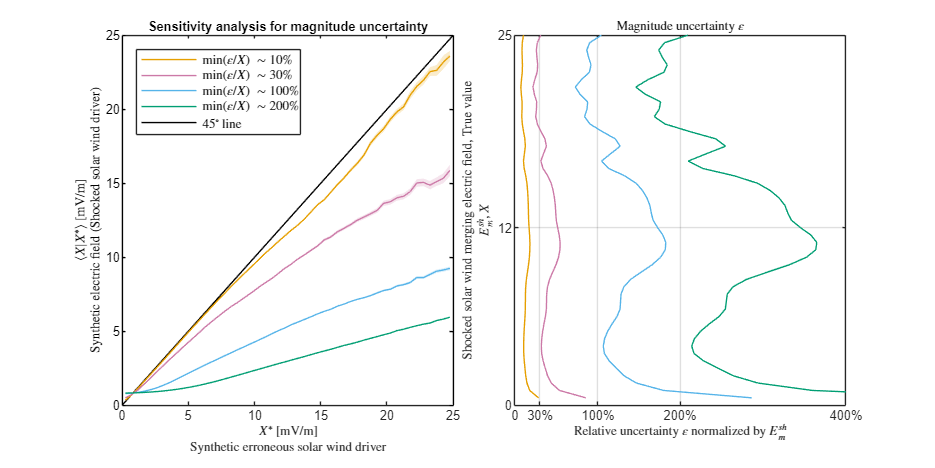

figS4_4=figure;
resize_figure(figS4_4,90,180);

tiledlayout(1,2,"TileSpacing","tight");

nexttile


p0 = plot(XBins,XBins,'-k');
hold on;
ylim([0,25]);
ylabel({'$ \langle X|X^* \rangle$ [mV/m]','Synthetic electric field (Shocked solar wind driver)'},'Interpreter','latex');
set(gca,'YColor',[0 0 0]);


p10 = plot_curve(EXIgWI_10,'#e69f00'); % 10% magnitude uncertainty (smaller than our calculation)
p30 = plot_curve(EXIgWI_30,'#cc79a7'); % 30% magnitude uncertainty (what we use)
p100 = plot_curve(EXIgWI_100,'#56b4e9'); % 100% magnitude uncertainty (larger than our calculation)
p200 = plot_curve(EXIgWI_200,'#009e73'); % 200% magnitude uncertainty (larger than our calculation)
ylim([0,25]);
xlim([0,25]);
xlabel({'$X^*$ [mV/m]','Synthetic erroneous solar wind driver'},'Interpreter','latex');
legend([p10,p30,p100,p200,p0],...
    'min($\varepsilon/X$) $\sim 10\%$',...
    'min($\varepsilon/X$) $\sim 30\%$',...
    'min($\varepsilon/X$) $\sim 100\%$',...
    'min($\varepsilon/X$) $\sim 200\%$',...
    '45$^\circ$ line', ...
    'Interpreter',"latex",'Location','northwest');
fontname('Helvetica');
fontsize(7, "points")
title('Sensitivity analysis for magnitude uncertainty','Interpreter',"none");

nexttile
XBins = 0:0.5:25;

plot(0.1.*0.3.^-1.*bayanefit(XBins')./XBins',XBins,'','Color','#e69f00');
hold on;
plot(bayanefit(XBins')./XBins',XBins,'','Color','#cc79a7');
hold on;
plot(1.*0.3.^-1.*bayanefit(XBins')./XBins',XBins,'','Color','#56b4e9');
hold on;
plot(2.*0.3.^-1.*bayanefit(XBins')./XBins',XBins,'','Color','#009e73');

xlim([0,4]);
ylim([0,25]);
xlabel('Relative uncertainty $\varepsilon$ normalized by $E_m^{sh}$','Interpreter',"latex");
ylabel({'Shocked solar wind merging electric field, True value','$E_m^{sh},X$'},'Interpreter',"latex");
title('Magnitude uncertainty $\varepsilon$','Interpreter',"latex");
set(gca,'YTick',[0,12,25],'XTick',[0,0.3,1,2,4],'XTickLabel',{"0","30%","100%","200%","400%"});
grid on;
fontsize(7,"points");
fontname('Helvetica');


if setExportFig
    %exportgraphics(figS4_4,[outputFolder,'ExtendedDataFigure9.pdf'],'ContentType','vector');
    exportgraphics(figS4_4,[outputFolder,'ExtendedDataFigure9.png'],'Resolution',600);
end

## Functions

function B = interp_nans(A)

## interp_nans.m This function removes nan by interpolating along altitude

%--------------------------------------------------------------------------
% Input
%------
% A - Input altitude vs. time matrix [nh x nT]
%--------------------------------------------------------------------------
% Output
%-------
% B - Interpolated altitude vs. time matrix, along the altitude directon
%     with nans removed [nh x nT]
%--------------------------------------------------------------------------
% Modified: 17th Jan 2018
% Created : 25th Sep 2016
% Author  : Nithin Sivadas
% Ref     :
%--------------------------------------------------------------------------

x=1:1:size(A,1);

for ty=1:1:size(A,2)

    y=A(:,ty);
    xi=x(find(~isnan(y)));
    yi=y(find(~isnan(y)));

    if sum(isnan(y))< size(A,1)-2
        B(:,ty)=interp1(xi,yi,x,'linear','extrap');
    else
        B(:,ty)=A(:,ty);
    end

end

[isThereNAN, totalNAN] = check_nan(B);

end

function [isThereNAN, totalNAN] = check_nan(thisArray)

## check_nan.m Check if there is any nan values in the given array

%--------------------------------------------------------------------------
% Input
%------
% thisArray : An array or a matrix
%--------------------------------------------------------------------------
% Output
%-------
% isThereNAN : A boolean variable, True => there is nan values in the
%              array, and False => there is no nan values in the array
% totalNAN   : The total number of NAN values
%
%--------------------------------------------------------------------------
% Modified: 22nd Sep 2016
% Created : 22nd Sep 2016
% Author  : Nithin Sivadas
% Ref     :
%--------------------------------------------------------------------------

thisArrayNAN = isnan(thisArray);
totalNAN = sum(thisArrayNAN(:));

if totalNAN>0
    isThereNAN = true;
else
    isThereNAN = false;
end

if isThereNAN==true
    warning(['There are ',num2str(totalNAN),...
        ' nan values in your data. The results may not be accurate.']);
end

end


function resize_figure( figureHandle, vert, horz )

## resize_figure.m Resizes figure into a standard paper size

%--------------------------------------------------------------------------
% Input
%------
% figureHandle
% vert - Vertical page size in mm (Default Letter Size)
% horz - Horizontal page size in mm (Default Letter Size)

if nargin<3 || isempty(horz)
    horz = 215.9;
end
if nargin<2 || isempty(vert)
    vert = 279.4;
end

% Centimeter Units
X = horz/10;
Y = vert/10;
xMargin = 0;
yMargin = 0;
xSize = X - 2*xMargin;
ySize = Y - 2*yMargin;

% Figure size displayed on screen
movegui(figureHandle, 'center');
set(figureHandle,'color','w');
set(figureHandle, 'Units', 'centimeters', 'Position', [0 0 xSize ySize])
end

% Function to plot a conditional expectation
function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
hold on;
X2 = [x, fliplr(x)];
inBetween = [ci(:,1)', fliplr(ci(:,2)')];
fill(X2,inBetween,"",'FaceColor',color,'LineStyle','none','FaceAlpha',alpha);
end

function p = plot_2D_error(Y,X,P,yLabel)
p = pcolor(Y,X,P);
set(p,'EdgeColor','none');
colorbar_thin('YLabel',yLabel);
end


% Function to calculate a conditional expectation of Y given X
% output is <Y|X>
function curve = create_curve(X, Y, Ei)

if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E;

end